# NWB Intracellular Electrophysiology Tutorial

## This tutorial

We will create fake data for a basic intracellular electrophysiology experiment and add it to an NWB File. The steps covered include:

- Creating an NwbFile object

- Creating and adding Devices and Electrodes

- Creating and adding Stimulus and Response Traces

- Generating a SweepTable

- Writing to an NWB file

- Reading from an NWB file

## Set up the NWB file

An NWB file represents a single session of an experiment. Each file must have a `session_description`, `identifier`, and `session_start_time`. Create a new `NWBFile` object with those and additional metadata. For all MatNWB functions, we use the Matlab method of entering keyword argument pairs, where arguments are entered as name followed by value.

All properties with the prefix `general` contain context for the entire experiment such as lab, institution, and experimentors. The `identifier` property is used to distinguish one session from another within an experiment, and this string should be unique to all other files, for example, concatenated lab name, file creation date/time and experimentalist, or a hash of these and/or other values.

experimenter = 'Dr. Bilbo Baggins';
lab = 'Bag End Laboratory';
my_ID = [experimenter ' ' lab];

nwb = NwbFile('session_description', 'My first synthetic IC ephys recording',...
              'identifier', my_ID, ...
              'session_start_time', datetime(2018, 1, 21, 2, 30, 3), ...
              'general_experimenter', experimenter, ... % optional
              'general_lab', lab, ... % optional
              'general_institution', 'University of Middle Earth at the Shire', ... % optional
              'general_experiment_description', 'I went on an adventure with thirteen dwarves to reclaim vast treasures.', ...
              'general_session_id', 'session_1234'); % optional - lab specific ID for this session
              
nwb

nwb =   NwbFile with properties:

                                nwb_version: '2.2.4'
                                acquisition: [0×1 types.untyped.Set]
                                   analysis: [0×1 types.untyped.Set]
                           file_create_date: []
                                    general: [0×1 types.untyped.Set]
                    general_data_collection: []
                            general_devices: [0×1 types.untyped.Set]
             general_experiment_description: 'I went on an adventure with thirteen dwarves to reclaim vast treasures.'
                       general_experimenter: 'Dr. Bilbo Baggins'
                general_extracellular_ephys: [0×1 types.untyped.Set]
     general_extracellular_ephys_electrodes: []
                        general_institution: 'University of Middle Earth at the Shire'
                general_intracellular_ephys: [0×1 types.untyped.Set]
      general_intrac

## Devices and Electrode Metadata

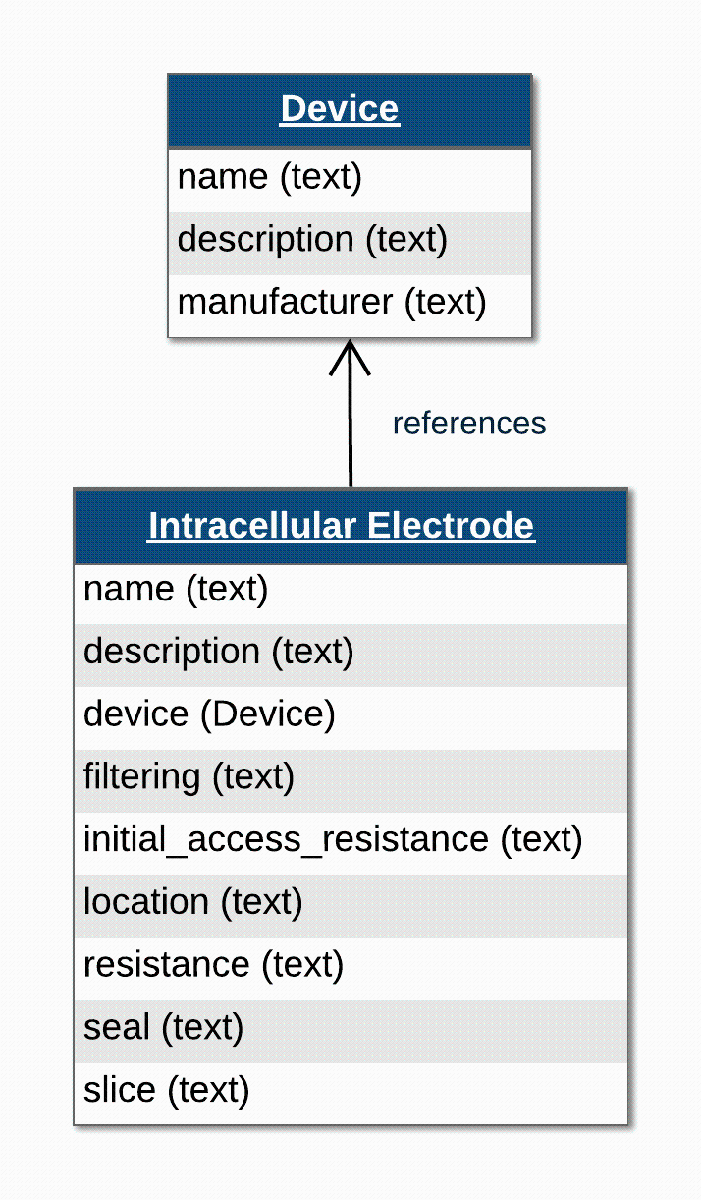 

Device metadata is represented by `Device` objects. `Device` objects are essentially just a list of device names; we create a DA/AD converter device for our electrode here and add it to our file.

device_name = 'Heka ITC-1600';

nwb.general_devices.set(device_name, types.core.Device());
device_link = types.untyped.SoftLink(['/general/devices/' device_name]);

To store electrode metadata, we create an `IntracellularElectrode` object with this device and additional metadata, and add a reference to the electrode in `general/intracellular_ephys:`

ic_elec_name = 'elec0';
ic_elec = types.core.IntracellularElectrode( ...
                                            'device', device_link, ...
                                            'description', 'An intracellular electrode');

nwb.general_intracellular_ephys.set(ic_elec_name, ic_elec);
ic_elec_link = types.untyped.SoftLink(['/general/intracellular_ephys/' ic_elec_name]);

## Stimulus Traces

Intracellular stimulus and response data are represented with subclasses of `PatchClampSeries`. There are two classes for representing stimulus data: 

- `VoltageClampStimulusSeries`

- `CurrentClampStimulusSeries`

                                            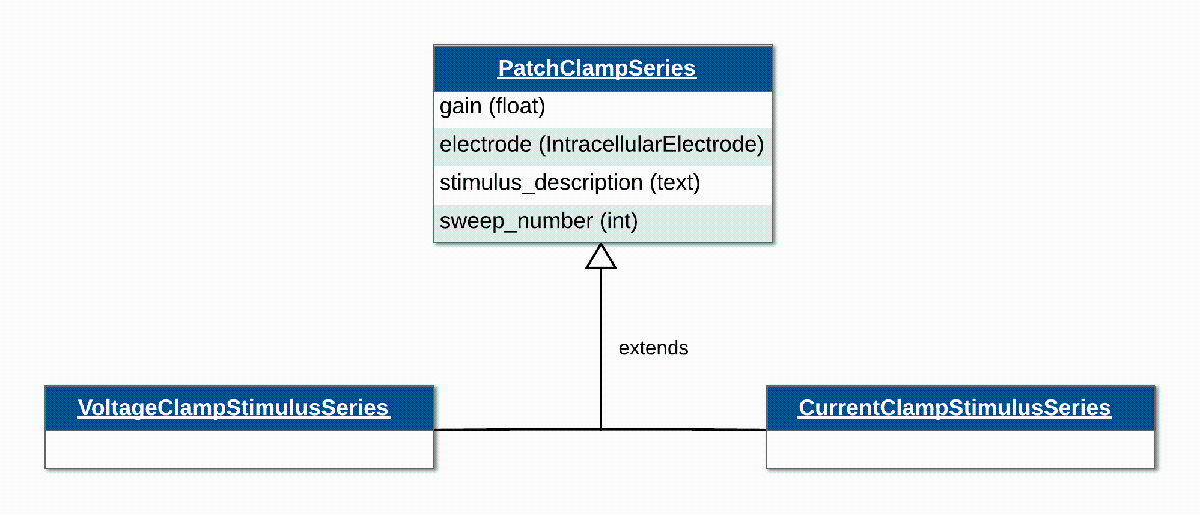

Both types of stimulus have similar syntax. We can add a user-defined `sweep_number` to associate this stimulus `PatchClampSeries` with other simultaneously recorded traces.

% Create some fake data samples and timestamps
data = ones(1,100);
timestamps = linspace(0,1,100);

% Add metadata for this stimulus
description = 'An intracellular ephys CC stimulus';
stimulus_name = 'constant_injection_0';

% Add a sweep number to group the stimulus with the corresponding response
sweep_number = 0;

ccs0 = types.core.CurrentClampStimulusSeries( ...
                                    'electrode', ic_elec_link, ...
                                    'gain', 0.02, ...
                                    'stimulus_description', description, ...
                                    'data_unit', 'pA', ...
                                    'data', data, ...
                                    'timestamps', timestamps, ...
                                    'sweep_number', sweep_number);

% Add the stimulus trace to our NWBFile
nwb.stimulus_presentation.set(stimulus_name, ccs0);
                          
% Now create second sweep
data1 = ones(1,100)*3;
timestamps = linspace(1.5,2.5,100);
description = 'A second intracellular ephys CC stimulus';
stimulus_name = 'constant_injection_1';
sweep_number = 1;

ccs1 = types.core.CurrentClampStimulusSeries( ...
                                    'electrode', ic_elec_link, ...
                                    'gain', 0.02, ...
                                    'stimulus_description', description, ...
                                    'data_unit', 'pA', ...
                                    'data', data1, ...
                                    'timestamps', timestamps, ...
                                    'sweep_number', sweep_number);


% Add it to the NWBFile
nwb.stimulus_presentation.set(stimulus_name, ccs1);

## Response Traces

There are three classes for representing response data:  

- `VoltageClampSeries` 

- `CurrentClampSeries`

- `IZeroClampSeries`

                                               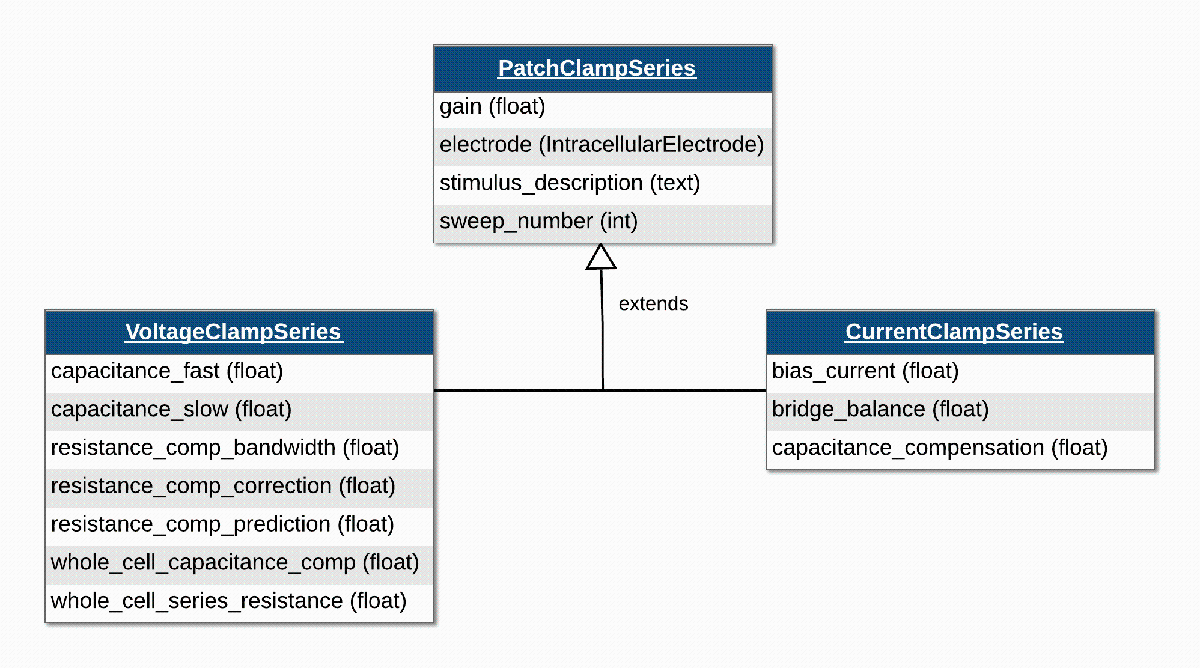

Voltage and current clamp data differ in the available metadata properties as shown in the class diagram, but the time series data has similar syntax across the different classes. Here we generate our data and define the relevant metadata, and then add the `CurrentClampSeries` to the file.

% Create some fake response datapoints. 
% We will use the timestamps we generated for the stimulus.
data = ones(1,100) * 2;
timestamps = linspace(0,1,100);

% Additional metadata 
response_name = 'constant_response_0';
stimulus_description = 'constant_injection_0';

% Sweep number for grouping
sweep_num = 0;

cc0 = types.core.CurrentClampSeries( ...
                          'bias_current', 10e-12, ... % Unit: amperes
                          'bridge_balance', [], ... % unknown
                          'capacitance_compensation', 4.5e-9, ... % Unit: farads
                          'timestamps', timestamps, ... % seconds
                          'data', data, ...
                          'data_unit', 'volts', ...
                          'electrode', ic_elec_link, ...
                          'gain', 0.02, ...
                          'stimulus_description', stimulus_description, ...
                          'sweep_number', sweep_num);
                      
% Add it to the NWBFile                   
nwb.acquisition.set(response_name, cc0);


% Generate a response for the second sweep
data1 = ones(1,100) * 4;
timestamps = linspace(1.5,2.5,100);
response_name = 'constant_response_1';
stimulus_description = 'constant_injection_1';

sweep_num = 1;

cc1 = types.core.CurrentClampSeries( ...
                          'bias_current', 10e-12, ... % Unit: amperes
                          'bridge_balance', [], ... % unknown
                          'capacitance_compensation', 4.5e-9, ... % Unit: farads
                          'timestamps', timestamps, ... % seconds
                          'data', data1, ...
                          'data_unit', 'volts', ...
                          'electrode', ic_elec_link, ...
                          'gain', 0.02, ...
                          'stimulus_description', stimulus_description, ...
                          'sweep_number', sweep_num);
                      
nwb.acquisition.set(response_name, cc1);

## Generating a Sweep Table

Sweep tables in MatNWB are `DynamicTables`. For further information on using `DynamicTables`, please refer to the documentation. To build a `SweepTable` we need to create `VectorData` objects for the sweep series and their associated sweep numbers, and a `VectorIndex` object for correctly indexing into the series data.

% Create a VectorData object with the sweep numbers for each row of the
% SweepTable
sweep_nums = types.hdmf_common.VectorData('data', [0, 1], ...
                                          'description','sweep numbers');
                             
% Create ObjectViews to reference the response traces in /acquisition by name                             
sweep_0 = types.untyped.ObjectView('/acquisition/constant_response_0');
sweep_1 = types.untyped.ObjectView('/acquisition/constant_response_1');

sweep_series_objects = [sweep_0, sweep_1];

% Create a VectorIndex for our series data
% Note the target location
series_ind = types.hdmf_common.VectorIndex(...
  'data', [0, 1],... % 0-based indices to sweep_series_objects
  'target', types.untyped.ObjectView('/general/intracellular_ephys/sweep_table/series'));

% Create a VectorData object for our sweep data
series_data = types.hdmf_common.VectorData(...
  'data', sweep_series_objects,...
  'description', 'Jagged Array of Patch Clamp Series Objects');

% Generate the SweepTable
sweepTable = types.core.SweepTable(...
    'colnames', {'series', 'sweep_number'},...
    'description', 'My Sweep Table',...
    'id', types.hdmf_common.ElementIdentifiers('data', [0 1]),...
    'series_index', series_ind,...
    'series', series_data,...
    'sweep_number', sweep_nums);

% Add the SweepTable to our NWBFile
nwb.general_intracellular_ephys_sweep_table = sweepTable;


## Write the file

nwbExport(nwb, 'icephys_basics_hck8_mat.nwb')

## Reading NWB data

For more detailed information on loading `PatchClampSeries` data, refer to the tutorials on NWB basics for loading and handling data. We use `nwbRead` to load the file: 

nwb_in = nwbRead('icephys_basics_hck8_mat.nwb');

The available stimulus traces can be found in `stimulus_presentation`:

keys(nwb_in.stimulus_presentation)

ans = 1×2 cell array
    {'constant_injection_0'}    {'constant_injection_1'}


And we can use `get(name)` to load the data:

stim1 = nwb_in.stimulus_presentation.get('constant_injection_1').data.load(1,10,100)

stim1 =      3
     3
     3
     3
     3
     3
     3
     3
     3
     3


Similarly, we can retrieve response traces from `acquisition`:

rsp0 = nwb_in.acquisition.get('constant_response_0').data.load(1,10,100)

rsp0 =      2
     2
     2
     2
     2
     2
     2
     2
     2
     2


And here is code to retrieve traces from the `SweepTable` by `sweep_number`:

sweepTable = nwb_in.general_intracellular_ephys_sweep_table;

% Sweep number we want to search for
sweepNumber = 0;
rowIndex = find(sweepNumber == sweepTable.sweep_number.data.load());

seriesIndices = sweepTable.series_index.data.load();
seriesObjects = sweepTable.series.data;

sweepSeries = cell(size(rowIndex));
for i = 1:length(rowIndex)
    index = rowIndex(i);
    % note that we must convert the start index to MATLAB    
    % we do the same for the end index though its 0-indexed is offset by
    % the fact that it is an exclusive range.
    % the true conversion would be seriesIndices(index+1) + 1 - 1;
    seriesStart = seriesIndices(index) + 1;
    if index == length(seriesIndices)
        seriesEnd = length(seriesObjects);
    else
        seriesEnd = seriesIndices(index+1);
    end
    sweepSeries{i} = seriesObjects(seriesStart:seriesEnd);
end
sweepSeries = [sweepSeries{:}]

sweepSeries =   ObjectView with properties:

    path: '/acquisition/constant_response_0'


# Learn more!

## MATLAB tutorials

- [Extracellular electrophysiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/ecephys.html)

- [Calcium imaging](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/ophys.html)